# Gas Prices in the 1990's vs 2000's

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

gasprices = readtable("./data/gasprices.csv", "Range", "A5:K24");

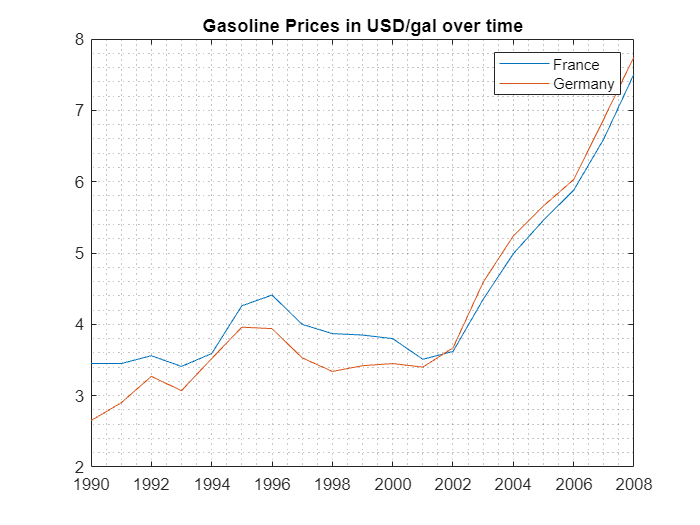

Year = gasprices.Year;
France = gasprices.France;
Germany = gasprices.Germany;

Fr2 = France(2);
France(1) = Fr2; % replace a missing value

plot(Year,France)
hold on
grid minor
plot(Year,Germany)
hold off
title("Gasoline Prices in USD/gal over time")
legend("France","Germany")

## Task 1

First, you will create a vector of indices of the data corresponding to the 1990s.  You can use the `:` operator to create evenly spaced vectors.

`x` `=` `2``:``5`

    `2` `3` `4` `5`

idx = 1:10;

## Task 2

To extract multiple elements, use a vector to index into another vector.

`v` `=` `[``3` `4` `5` `7``]`

`v``([``1` `3``])`

    `3` `5`

This vector can be defined within the parentheses or you can reference another variable.

`nums` `=` `[``2` `3``]``;`

`v``(``nums``)`

    `4` `5`

Fr90s = France(idx)

Fr90s =     3.4500
    3.4500
    3.5600
    3.4100
    3.5900
    4.2600
    4.4100
    4.0000
    3.8700
    3.8500


## Task 3

Ger90s = Germany(idx)

Ger90s =     2.6500
    2.9000
    3.2700
    3.0700
    3.5200
    3.9600
    3.9400
    3.5300
    3.3400
    3.4200


## Task 4

The years are stored in the variable `Year`. You can extract the corresponding years using the same indexing variable.

`Year``(``idx``)`

To plot two lines on a graph, use `hold` `on` and `hold` `off`.

`plot``(``x1``,``y1``)`

`hold` `on`

`plot``(``x2``,``y2``)`

`hold` `off`

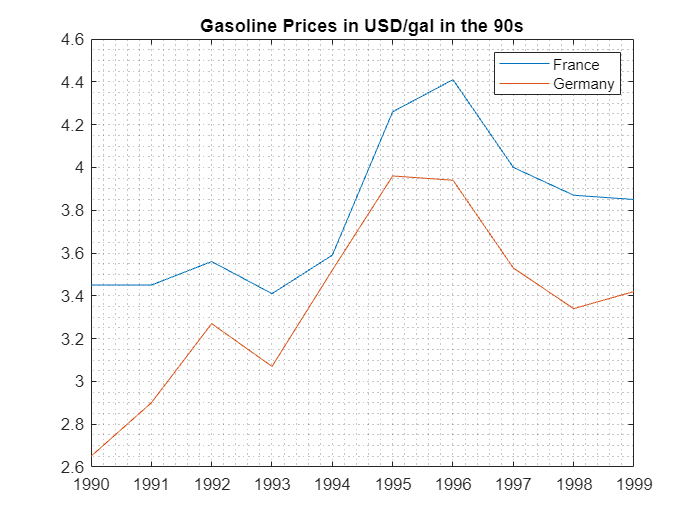

plot(Year(idx),Fr90s)
hold on
grid minor
plot(Year(idx),Ger90s)
hold off

title("Gasoline Prices in USD/gal in the 90s")
legend("France","Germany")

## Task 5

Now you will extract the data from the 2000s. 

Recall that you can also use the `end` keyword to index into a vector and do arithmetic with it.

`v = [1 3 5 7 9];`

`v(end)`

`    9`

`v(end-3:end)`

`    5 7 9`

Fr00s = France(11:end)

Fr00s =     3.8000
    3.5100
    3.6200
    4.3500
    4.9900
    5.4600
    5.8800
    6.6000
    7.5100


Ger00s = Germany(11:end)

Ger00s =     3.4500
    3.4000
    3.6700
    4.5900
    5.2400
    5.6600
    6.0300
    6.8800
    7.7500


## Task 6

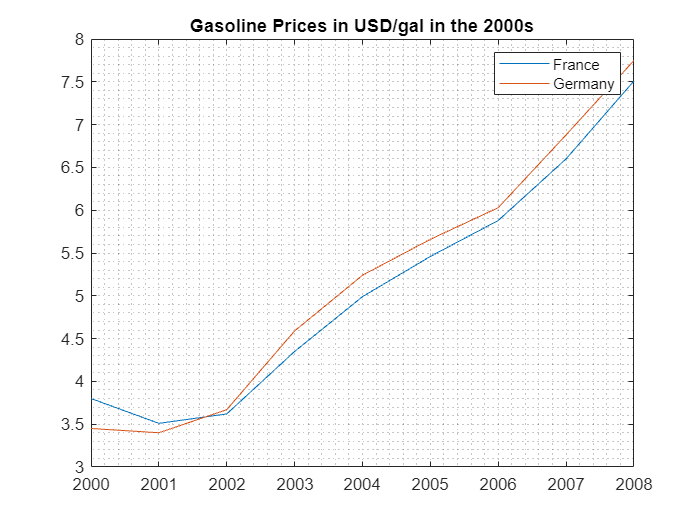

plot(Year(11:end),Fr00s)
hold on
grid minor
plot(Year(11:end),Ger00s)
hold off

title("Gasoline Prices in USD/gal in the 2000s")
legend("France","Germany")